# Gage R and R for Material Testing

A guided introduction to repeatability and reproducibility using synthetic tensile-strength measurements.

The example data are illustrative only and do not represent customer measurements or acceptance limits.

## Engineering question

Before using test results to compare materials, determine whether the measurement system contributes substantial variation. Repeatability describes variation when the same operator repeats a measurement. Reproducibility describes variation between operators.

**Agent prompt:** Explain the roles of Part, Operator and Measurement in this dataset. Identify the experimental unit and explain why measurements from the same part are not independent.

## Load the synthetic measurements

dataFolder = fullfile(pwd,"data");
gageData = readtable(fullfile(dataFolder,"gage_rr_material_testing.csv"));
head(gageData)
summary(gageData)

## Review part and operator patterns

Plot repeated measurements by part and operator. Look for large within-part spread and systematic differences between operators.

boxchart(categorical(gageData.PartID),gageData.TensileStrength,GroupByColor=categorical(gageData.Operator));
xlabel("Part ID")
ylabel("Tensile strength (MPa)")
title("Repeated material-test measurements by operator")
legend("Location","best")
grid on

**Agent prompt:** Describe visible within-part and between-operator patterns. Do not make a pass/fail decision because the data are synthetic and no customer acceptance rule was provided.

## Analyze with the Gage R and R Analyzer app

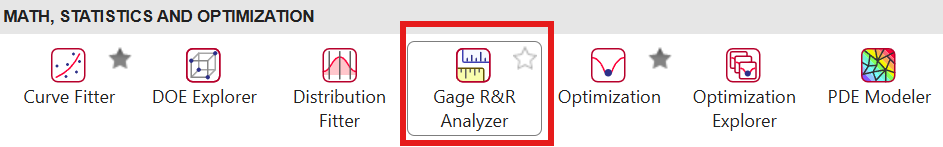

In MATLAB R2026b, open Apps and select Gage R and R Analyzer. Import `gage_rr_material_testing.csv`, 

set PartID as the part variable, Operator as the operator variable, and TensileStrength as the measurement. 

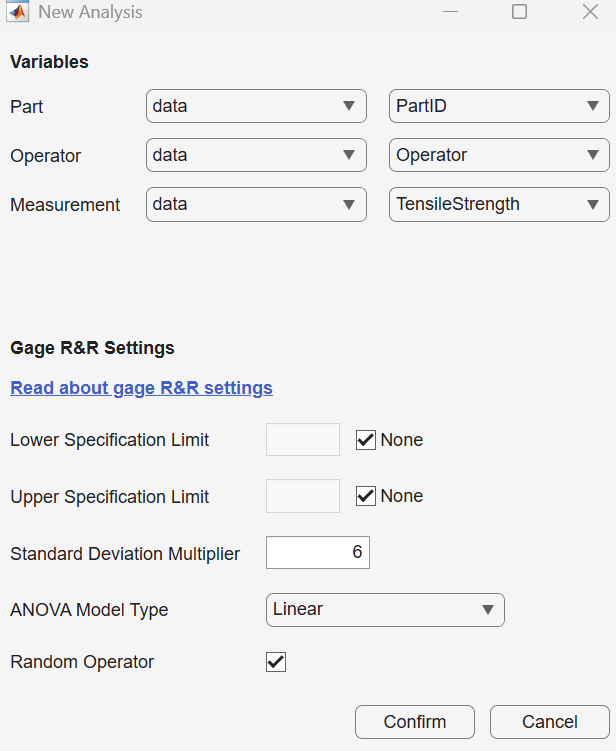

Review the variance components and plots.

The Statistics and Machine Learning Toolbox also includes `gagerr` for code-based analysis. Confirm the installed release syntax and assumptions in MATLAB help before using it with customer data.

**Agent prompt:** Create a step-by-step checklist for analyzing this table in Gage R and R Analyzer. Include the required variable mapping, plots to inspect, and questions to ask about the test method and resolution.

## Discussion and next step

Ask the laboratory team how samples are selected, how many operators and repeats are practical, whether the method is destructive, and what variation is acceptable for the intended decision.

**Interpretation guardrail:** A Gage R and R result evaluates the measurement process under the study design. It does not certify the material or prove the test method is suitable for every decision. \